from = 1;
to = 536;
size_signal = size(EEGDataMovment)

size_signal =         5368           8



for j=1:8
    for i=1:10
        if to<size_signal(1)
            mov_section =EEGDataMovment(from:to,j);
            Mean_EEG(i,j) = mean(mov_section);
            Std_EEG(i,j) = std(mov_section);
            Var_EEG(i,j) = var(mov_section);
    
            if j<2
                sections(i,:)=[from,to];
            end

            from = from + 536;
            to = to + 536;
        end
    end
    from = 1;
    to = 536;
end
%a=array2table(Std_EEG,'VariableNames',{'EEG1' 'EEG2' 'EEG3' 'EEG4' 'EEG5' 'EEG6' 'EEG7' 'EEG8'})
data = table(Std_EEG,Mean_EEG,Var_EEG)

data = 10×3 table
     Std_EEG       Mean_EEG      Var_EEG  
    __________    __________    __________

    1×8 double    1×8 double    1×8 double
    1×8 double    1×8 double    1×8 double
    1×8 double    1×8 double    1×8 double
    1×8 double    1×8 double    1×8 double
    1×8 double    1×8 double    1×8 double
    1×8 double    1×8 double    1×8 double
    1×8 double    1×8 double    1×8 double
    1×8 double    1×8 double    1×8 double
    1×8 double    1×8 double    1×8 double
    1×8 double    1×8 double    1×8 double


%remove initial noise
data(1,:) = [];
Std_EEG(1,:) = [];
Mean_EEG(1,:) = [];
Var_EEG(1,:) = [];

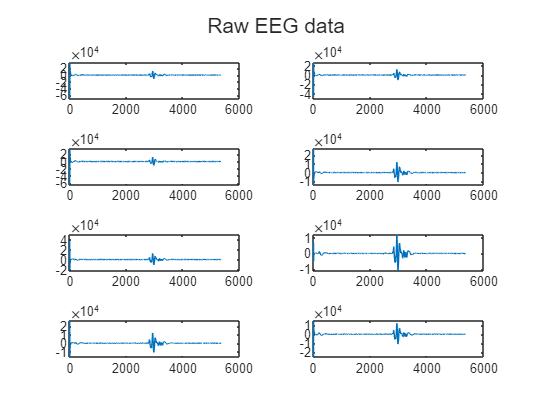

%original data
t = tiledlayout(4,2);

for j=1:8
    nexttile
    plot(EEGDataMovment(:,j))
end
title(t,'Raw EEG data')


%selected data
[max_value,index]=max(data.Std_EEG)

max_value = 1.0e+03 *

    3.8628    3.8623    3.8647    3.8639    3.8617    3.8643    3.8650    3.8662


index =      5     5     5     5     5     5     5     5


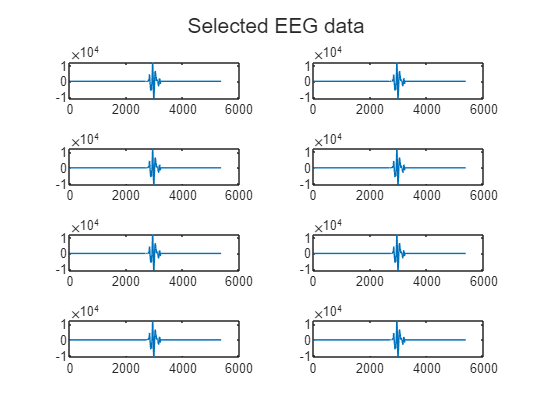

a = index(1)+1;
section = sections(a,:);
selected_part1 = zeros(section(1)-1,1);
selected_part3 = zeros(size_signal(1)-section(2),1);
for j=1:8
    selected_part2 = EEGDataMovment(section(1):section(2),j);
    selected_part(:,j) = [selected_part1;selected_part2;selected_part3];
end
r = tiledlayout(4,2);
for i=1:8
    nexttile
    plot(selected_part(:,i))
end
title(r,'Selected EEG data')